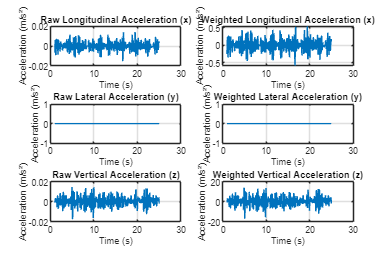

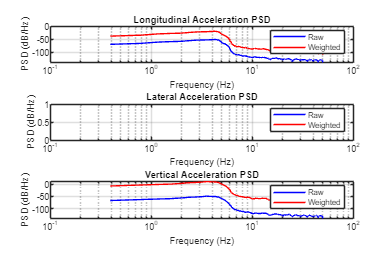


--- Ride Quality Analysis Results ---
Frequency-weighted RMS values:
  Longitudinal (x): 0.166 m/s²
  Lateral (y):     0.000 m/s²
  Vertical (z):    4.569 m/s²
  Total:          4.572 m/s²

Vibration Dose Values (VDV):
  Longitudinal (x): 0.496 m/s¹.⁷⁵
  Lateral (y):     0.000 m/s¹.⁷⁵
  Vertical (z):    13.668 m/s¹.⁷⁵
  Total:          13.668 m/s¹.⁷⁵

Crest Factors:
  Longitudinal (x): 3.5
  Lateral (y):     NaN
  Vertical (z):    3.7

Ride Comfort Assessment: Extremely uncomfortable


% good typical results
% load flightData_Rigid_v0.mat
% [rms_total_control, vdv_total_control, c_f_control] = ride_quality_analysis(flight_data, true);
% load flightData_AC_v0.mat
% [rms_total, vdv_total, c_f] = ride_quality_analysis(flight_data, true);


% load flightData_Rigid.mat
% [rms_total_control, vdv_total_control, c_f_control] = ride_quality_analysis(flight_data, true);
% 
% load flightData_AC.mat
% [rms_total, vdv_total, c_f] = ride_quality_analysis(flight_data, true);

load Dryden_opt_flightData_Rigid.mat
load flightData_Rigid_v0.mat
load flightData_Rigid.mat
[rms_total_control, vdv_total_control, c_f_control] = ride_quality_analysis(flight_data, true);

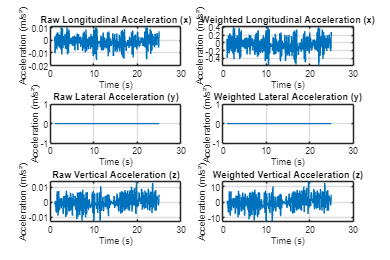

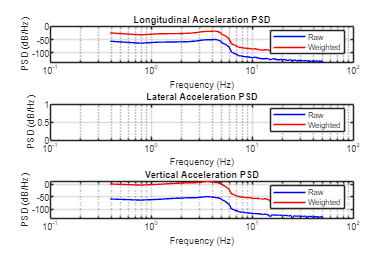


--- Ride Quality Analysis Results ---
Frequency-weighted RMS values:
  Longitudinal (x): 0.183 m/s²
  Lateral (y):     0.000 m/s²
  Vertical (z):    4.142 m/s²
  Total:          4.146 m/s²

Vibration Dose Values (VDV):
  Longitudinal (x): 0.534 m/s¹.⁷⁵
  Lateral (y):     0.000 m/s¹.⁷⁵
  Vertical (z):    11.952 m/s¹.⁷⁵
  Total:          11.952 m/s¹.⁷⁵

Crest Factors:
  Longitudinal (x): 3.2
  Lateral (y):     NaN
  Vertical (z):    3.2

Ride Comfort Assessment: Extremely uncomfortable


load Dryden_opt_flightData_AC.mat
load flightData_AC_v0.mat
load flightData_UnOpt.mat
load flightData_AC.mat
[rms_total, vdv_total, c_f] = ride_quality_analysis(flight_data, true);



% load flightData_UnOpt.mat
% [rms_total, vdv_total, c_f] = ride_quality_analysis(flight_data, true);

vdv_total_control

vdv_total_control = 13.6680

vdv_total

vdv_total = 11.9520

FOM_control = rms_total_control + vdv_total_control + sum(c_f_control)

FOM_control = NaN

FOM = rms_total + vdv_total + sum(c_f)

FOM = NaN

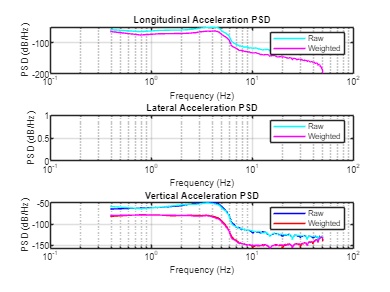


%now superimpose the plots 
figure
load flightData_Rigid.mat
load Dryden_opt_flightData_Rigid.mat
load flightData_Rigid_v0.mat
load flightData_Rigid.mat
% compute the ride quality of hte 
ax = flight_data.ax(:); % Ensure column vector
ay = flight_data.ay(:);
az = flight_data.az(:);
fs = flight_data.fs;
t = flight_data.t;

% Design ISO-2631 Frequency Weighting Filters
[Bx, Ax] = design_iso2631_filter('Wd', fs); % Longitudinal (x)
[By, Ay] = design_iso2631_filter('Wd', fs); % Lateral (y)
[Bz, Az] = design_iso2631_filter('Wk', fs); % Vertical (z)

% Apply frequency weighting with proper filter syntax
%% Define numerator & denominator for Wk
numWk = [1 32 1859 793.9 81.89];
denWk = [1 2261 7007 20640 79.96];
% Analog to discrete at sample rate fs
fs = flight_data.fs;  % e.g., 200 Hz
Ts = 1/fs;
[bdWk, adWk] = bilinear(numWk, denWk, fs);

% Define numerator & denominator for Wd
numWd = [0 14.55 6.026 7.714];     % leading zero for proper order
denWd = [1 51.65 47.66 15.02];
[bdWd, adWd] = bilinear(numWd, denWd, fs);

% Filter your acceleration signals
az_weighted = filter(bdWk, adWk, az);     % vertical axis
ax_weighted = filter(bdWd, adWd, ax);     % longitudinal
ay_weighted = filter(bdWd, adWd, ay);     % lateral

% Remove initial transient (1 second)
transient = round(1*fs);
t = t(transient:end);
ax_weighted = ax_weighted(transient:end);
ay_weighted = ay_weighted(transient:end);
az_weighted = az_weighted(transient:end);

figure
% Calculate PSD using Welch's method
nfft = 2^nextpow2(length(t)/10);
window = hann(nfft);
noverlap = nfft/2;
[pxx_x, f] = pwelch(ax, window, noverlap, nfft, fs);
[pxx_xw, ~] = pwelch(ax_weighted, window, noverlap, nfft, fs);

[pxx_y, ~] = pwelch(ay, window, noverlap, nfft, fs);
[pxx_yw, ~] = pwelch(ay_weighted, window, noverlap, nfft, fs);

[pxx_z, ~] = pwelch(az, window, noverlap, nfft, fs);
[pxx_zw, ~] = pwelch(az_weighted, window, noverlap, nfft, fs);

%Plot PSDs
subplot(3,1,1);
semilogx(f, 10*log10(pxx_x), 'b', f, 10*log10(pxx_xw), 'r');
title('Longitudinal Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);

subplot(3,1,2);
semilogx(f, 10*log10(pxx_y), 'b', f, 10*log10(pxx_yw), 'r');
title('Lateral Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);

subplot(3,1,3);
semilogx(f, 10*log10(pxx_z), 'b', f, 10*log10(pxx_zw), 'r');
title('Vertical Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);


hold on;

load flightData_AC.mat
load Dryden_opt_flightData_AC.mat
load flightData_AC_v0.mat
load flightData_UnOpt.mat
load flightData_AC.mat
% compute the ride quality of hte 
ax = flight_data.ax(:); % Ensure column vector
ay = flight_data.ay(:);
az = flight_data.az(:);
fs = flight_data.fs;
t = flight_data.t;

% Design ISO-2631 Frequency Weighting Filters
[Bx, Ax] = design_iso2631_filter('Wd', fs); % Longitudinal (x)
[By, Ay] = design_iso2631_filter('Wd', fs); % Lateral (y)
[Bz, Az] = design_iso2631_filter('Wk', fs); % Vertical (z)

% Apply frequency weighting with proper filter syntax
%% Define numerator & denominator for Wk
numWk = [1 32 1859 793.9 81.89];
denWk = [1 2261 7007 20640 79.96];
% Analog to discrete at sample rate fs
fs = flight_data.fs;  % e.g., 200 Hz
Ts = 1/fs;
[bdWk, adWk] = bilinear(numWk, denWk, fs);

% Define numerator & denominator for Wd
numWd = [0 14.55 6.026 7.714];     % leading zero for proper order
denWd = [1 51.65 47.66 15.02];
[bdWd, adWd] = bilinear(numWd, denWd, fs);

% Filter your acceleration signals
az_weighted = filter(bdWk, adWk, az);     % vertical axis
ax_weighted = filter(bdWd, adWd, ax);     % longitudinal
ay_weighted = filter(bdWd, adWd, ay);     % lateral

% Remove initial transient (1 second)
transient = round(1*fs);
t = t(transient:end);
ax_weighted = ax_weighted(transient:end);
ay_weighted = ay_weighted(transient:end);
az_weighted = az_weighted(transient:end);


% Calculate PSD using Welch's method
nfft = 2^nextpow2(length(t)/10);
window = hann(nfft);
noverlap = nfft/2;

[pxx_x, f] = pwelch(ax, window, noverlap, nfft, fs);
[pxx_xw, ~] = pwelch(ax_weighted, window, noverlap, nfft, fs);

[pxx_y, ~] = pwelch(ay, window, noverlap, nfft, fs);
[pxx_yw, ~] = pwelch(ay_weighted, window, noverlap, nfft, fs);

[pxx_z, ~] = pwelch(az, window, noverlap, nfft, fs);
[pxx_zw, ~] = pwelch(az_weighted, window, noverlap, nfft, fs);

%Plot PSDs
subplot(3,1,1);
semilogx(f, 10*log10(pxx_x), 'c', f, 10*log10(pxx_xw), 'm');
title('Longitudinal Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);

subplot(3,1,2);
semilogx(f, 10*log10(pxx_y), 'c', f, 10*log10(pxx_yw), 'm');
title('Lateral Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);

subplot(3,1,3);
semilogx(f, 10*log10(pxx_z), 'c', f, 10*log10(pxx_zw), 'm');
title('Vertical Acceleration PSD');
xlabel('Frequency (Hz)');
ylabel('PSD (dB/Hz)');
legend('Raw', 'Weighted');
grid on;
xlim([0.1 100]);